# EMT for EPANET-MSX

## **Initialize EPANET-MATLAB Toolkit**

Load all the paths in MATLAB. You should always begin with this command to load the toolkit.

start_toolkit

EPANET-MATLAB Toolkit Paths Loaded.


If you get an error message:

`'start_toolkit' is not found in the current folder or on the MATLAB path, but exists in:`

It means that you need to change the MATLAB current folder.

**Load a benchmark network**

Decide which benchmark network to use and load the network

% decide which network to load from the "/networks/" folder  
filename = 'net2-cl2.inp'; % you can also try 'net2-cl2.inp', 'Net3.inp', etc.

%call epanet class and load all data and functions in G structure
G = epanet(filename)

EPANET version {20200} loaded (EMT version {v2.2.4 - Last Update: 08/12/2022}).
<a href = "https://doi.org/10.5281/zenodo.831493">Publication DOI: 10.5281/zenodo.831493</a>
Loading File "net2-cl2.inp"...
Input File "net2-cl2.inp" loaded successfully.


G =   epanet with properties:

                                   ph: [1×1 lib.pointer]
                   ControlLevelValues: []
                     ControlLinkIndex: []
                     ControlNodeIndex: []
                         ControlRules: []
                    ControlRulesCount: 0
                             Controls: [1×1 struct]
                      ControlSettings: []
                         ControlTypes: {}
                    ControlTypesIndex: []
                           CurveCount: 0
                           CurveIndex: [1×0 int32]
                           CurvesInfo: [1×1 struct]
                      DemandModelCode: 0
                      DemandModelPmin: 0
                      DemandModelPreq: 0.1
                      DemandModelPexp: 0.5
                      DemandModelType: {'DDA'}
                EnergyEfficiencyUnits: 'percent'
                          EnergyUnits: 'kwatt-hours'
 

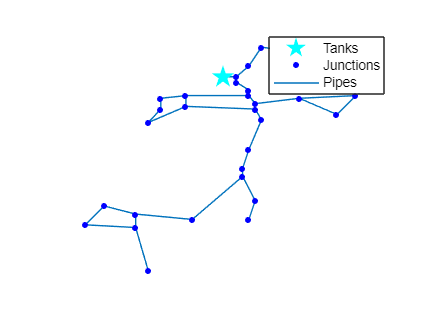

ans =   Axes with properties:

             XLim: [6.5 60.5]
             YLim: [-4.3 95.3]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.13 0.11 0.775 0.815]
            Units: 'normalized'

  Show all properties


G.plot

## **Multi-species chemical reactions**

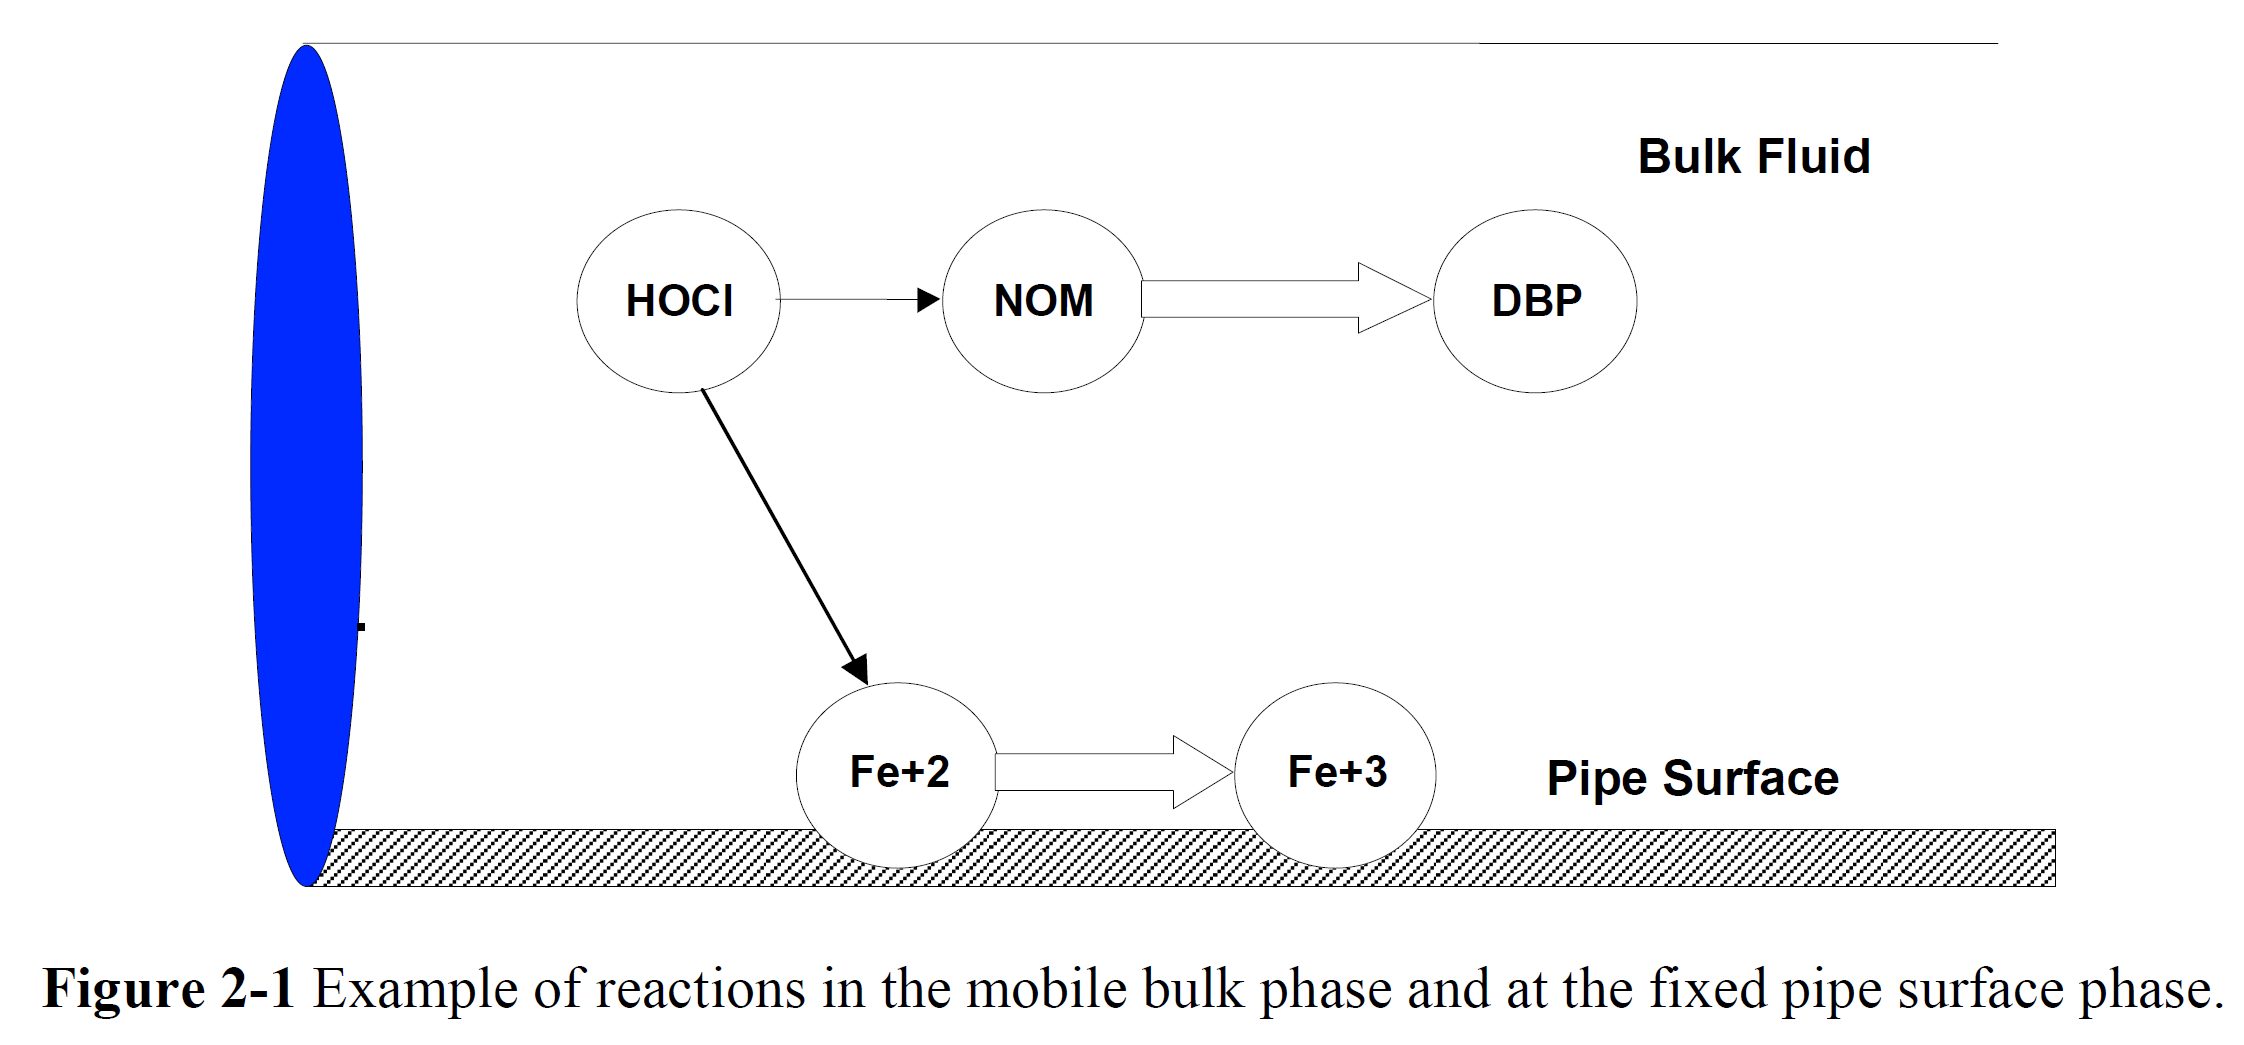

Reactions in water can be described using a set of Differential Algebraic Equations (DAE):


$$\frac{dx_b}{dt}=f(x_b,x_s,z_b,z_s)$$



$$\frac{dx_s}{dt}=g(x_b,x_s,z_b,z_s)$$



$$0=h(x_b,x_s,z_b,z_s)$$


These equations describe most of the reactions in water distribution systems. The solution methodology follows the following steps:

- Split the pipes into segments

- Solve the reaction equations for each segment

- Compute the advection (movement based on flows)

- Mix the bulk concentrations with the pipe wall concentrations 

- Recompute segmens

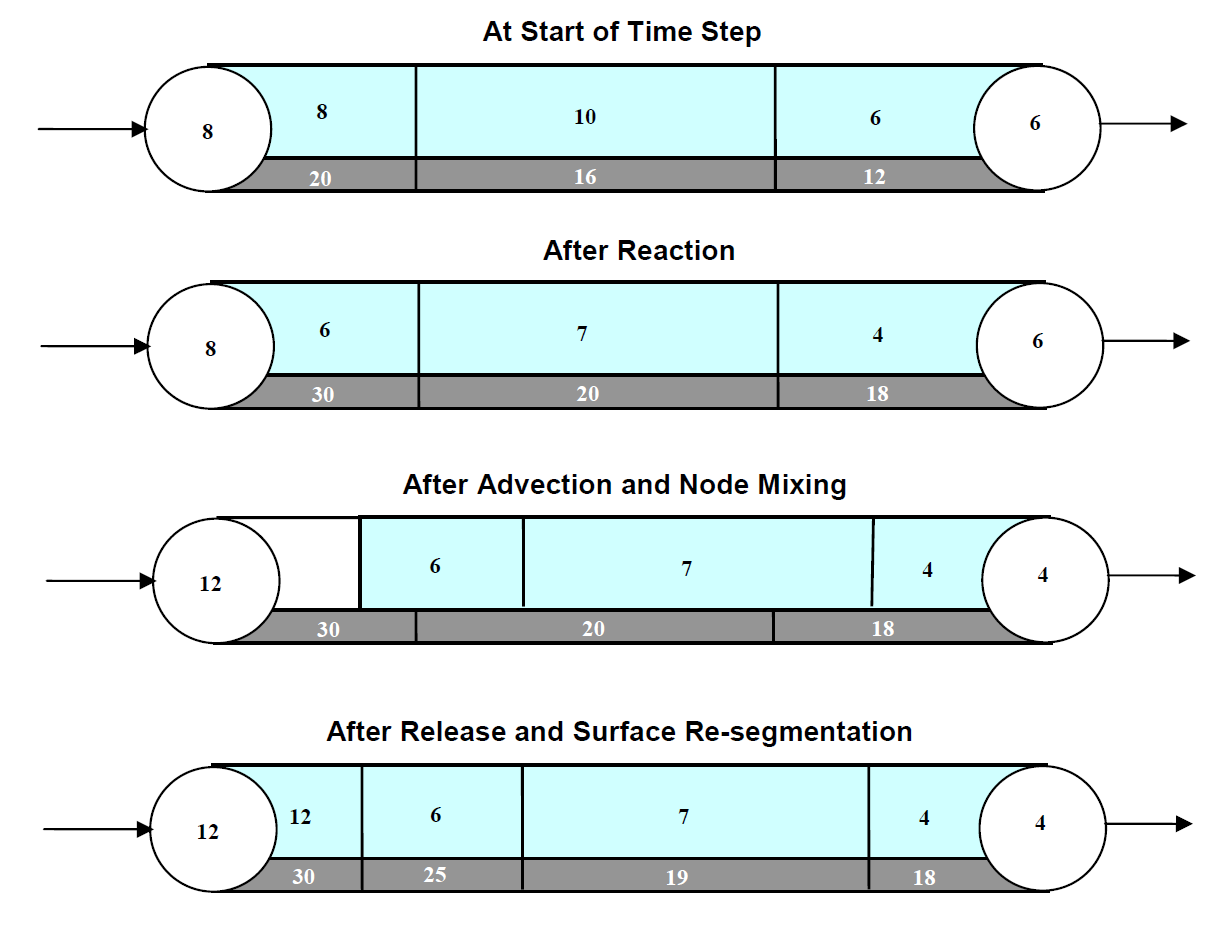

The set of diferential equations can be solved using an explicit method, e.g. **Runge-Kutta** or **Forward Euler** method.

** Chlorine reactions**

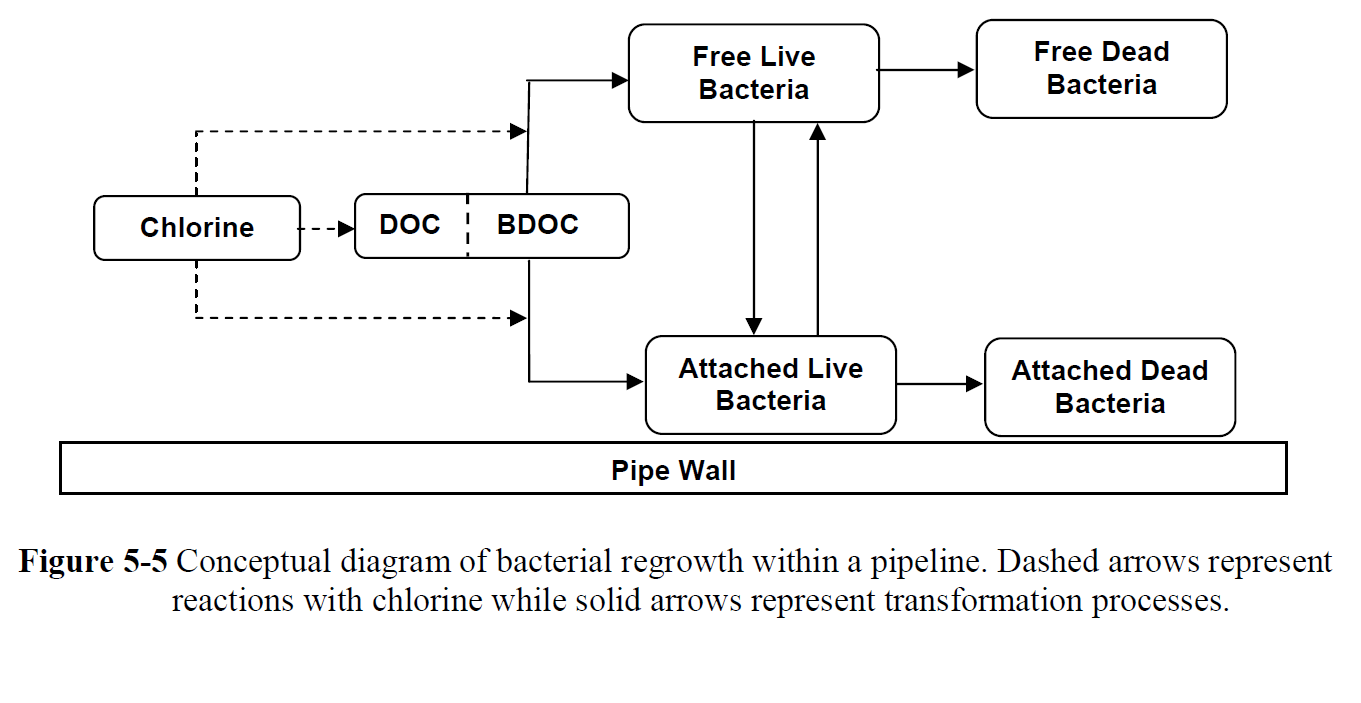

The most standard assumption is that Free Chlorine concentration is linear, i.e, 


$$\frac{dC(t)}{dt} = -k_bC(t)$$


Where $C(t)$ is the free chlorine concentration measured in $mg/L$.

% Example MSX file
fid = fopen('net2-cl2.msx','r')

fid =      3


c = fread(fid, inf, 'uint8=>char')'

c =     '[TITLE]
     NET2 Chlorine Example
     
     
     [OPTIONS]
     AREA_UNITS  FT2
     RATE_UNITS  DAY
     SOLVER      EUL
     TIMESTEP    300
     RTOL        0.001
     ATOL        0.001
     
     
     [SPECIES]
     BULK        CL2    MG  0.01 0.001
     
     
     [COEFFICIENTS]
     PARAMETER   Kb     0.3
     PARAMETER   Kw     1.0
     
     
     [TERMS]
     Kf     1.5826e-4 * RE^0.88 / D
     
     [PIPE]
     RATE        CL2    -Kb*CL2 - (4/D)*Kw*Kf/(Kw+Kf)*CL2
     
     
     [TANK]
     RATE        CL2    -Kb*CL2
     
     
     [SOURCES]
     ;CONC/MASS/FLOW/SETPOINT   <nodeID>      <specieID>     <strength>     (<tseriesID>)
     CONC                          1             CL2           0.8
     
     
     [QUALITY]
     GLOBAL          CL2   0.5
     NODE      26    CL2   0.1
     
     [PARAMETERS]
     ;PIPE        <pipeID>      <paramID>     <value>
     ;TANK        <tankID>      <paramID>     <value>
     
     [REPORT]
     NODES  2  20  23  26
 

**How to load an MSX file**

% Load EPANET-MSX file
G.loadMSXFile('net2-cl2.msx') % Load MSX file with reactions
qual_res_MSX = G.getMSXComputedQualitySpecie('CL2')

qual_res_MSX = struct with fields:
    NodeQuality: [661×36 double]
    LinkQuality: [661×40 double]
           Time: [661×1 double]


Q_msx = G.getMSXComputedQualityNode  % Compute water quality using MSX

Q_msx = struct with fields:
    Quality: {1×36 cell}
       Time: [661×1 double]


Plot MSX species in MATLAB Figure

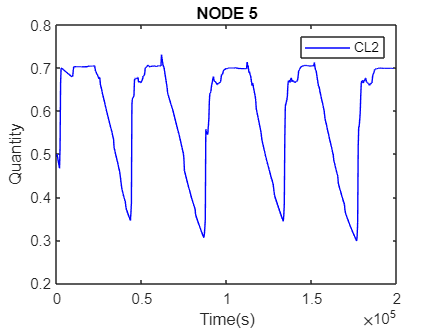

G.plotMSXSpeciesNodeConcentration(5,1)

**Another example**

% Get quality of specific nodes.
sensor_index = [2, 3, 5];
sensors_names = G.getNodeNameID(sensor_index)

sensors_names = 1×3 cell array
    {'2'}    {'3'}    {'5'}


QN = G.getMSXComputedQualityNode(sensor_index)

QN = struct with fields:
    Quality: {[661×1 double]  [661×1 double]  [661×1 double]}
       Time: [661×1 double]



% Get quality of specific links.
QL = G.getMSXComputedQualityLink(sensor_index)

QL = struct with fields:
    Quality: {[661×1 double]  [661×1 double]  [661×1 double]}
       Time: [661×1 double]



% Get species names.
type = G.getMSXSpeciesNameID;

% Get quality for specific species type (nodes and links).
MSX_comp = G.getMSXComputedQualitySpecie(type)

MSX_comp = struct with fields:
    NodeQuality: [661×36 double]
    LinkQuality: [661×40 double]
           Time: [661×1 double]


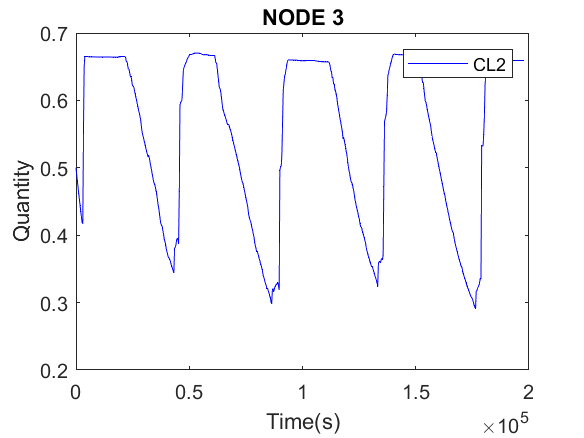


figure
G.plotMSXSpeciesNodeConcentration(3,1)

**Unload libraries**

G.unloadMSX;
G.unload;

EPANET Class is unloaded
